# SMC

Diseño y simulación de un controlador de modo deslizante para un modelo simplificado de un motor dc. 

lambda1 = 0; lambda2 = 0; delta_x1 = 0; 

Propiedades del motor

addpath("data/"); 

addpath("controllers/SMC"); 


load("TF.mat")
load("observer.mat"); 

% Files 

SIME_FILE = "controllers/SMC/design/smc.slx"; 

## Cálculo del beta

beta=100

beta =    100


MAX_PWM=100%beta

MAX_PWM =    100


a=1

a =      1


delta=90*pi/180

delta =    1.570796326794897


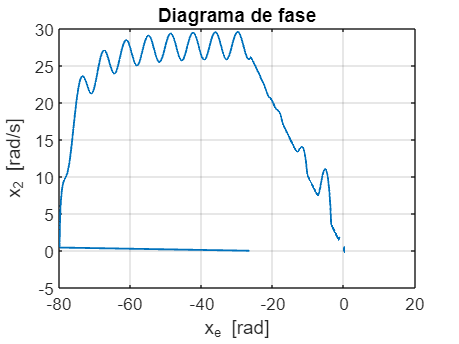


results = sim(SIME_FILE);

t = results.tout; % tiempo de simulación

% Estados del sistema
x1 = results.errorTheta.Data;
x2 = results.Omega.Data;
ref = ones(size(t))*delta*180/pi;
figure()


plot(x1, x2, '-', 'LineWidth',1); hold on; 
title("Diagrama de fase"); 
xlabel("x_e [rad]"); ylabel("x_2 [rad/s]");
grid on;

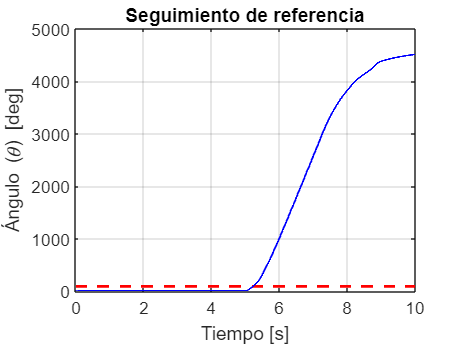


figure()
plot(t,ref,'r--','LineWidth',1.5);
%xline(0, 'k--'); yline(0, 'k--');
hold on
plot(t,results.Theta.Data*180/pi,'b','LineWidth',1);
hold off
xlabel("Tiempo [s]"); ylabel("Ángulo (\theta) [deg]"); 
title("Seguimiento de referencia");
grid on; 

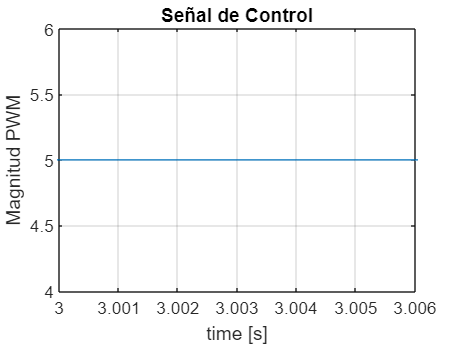


figure()
plot(t, results.U.Data); 
title("Señal de Control")
xlabel("time [s]"); 
ylabel("Magnitud PWM"); 
grid on; 
xlim([3 3.006])

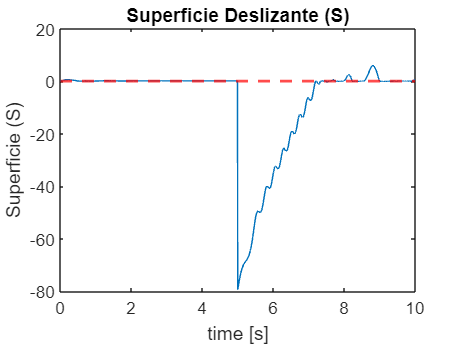


figure()
plot(t,a*x1+x2)
hold on; 
yline(0, 'r--','LineWidth',1.5);
hold off
title("Superficie Deslizante (S)")
xlabel("time [s]"); 
ylabel("Superficie (S)"); 

% condiciones iniciales 
x10 = 0; 
x20 = 0; 

delta_x1 = 0; %-pi/6; 

results = sim(SIME_FILE); 

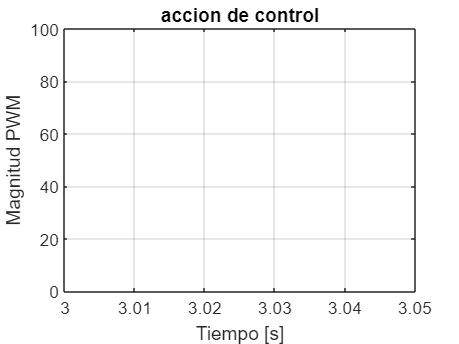



t = results.tout; % tiempo de simulación    

% Estados del sistema
x1 = results.Theta.Data;
x2 = results.Omega.Data;

% Accion de control 
figure()
u = results.U.Data; 
plot(t, u + beta);
title("accion de control");
ylabel("Magnitud PWM"); xlabel("Tiempo [s]"); 
axis([ 3 3.05 0 100]); grid on; 

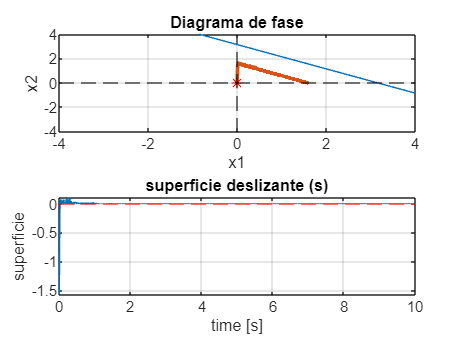




figure(); 
subplot(2, 1, 1);

% superficie deslizante 
x = -5:0.01:5; 
plot(x, -a*(x-2*delta));  hold on; 

plot(x1, x2, '-', 'LineWidth',2); hold on; 
title("Diagrama de fase"); 
xlabel("x1"); ylabel("x2"); 
axis([-4,4, -4, 4]); %axis([-abs(x10) * 1.2, abs(x10) * 1.5, -4, 4]); 
scatter(x10 - delta_x1, x20, 'r*'); 



xline(0, 'k--'); yline(0, 'k--'); 
grid on; 

subplot(2, 1, 2);

% Superficie deslizante 
s = results.s.Data; 


plot(t, s); hold on; 
yline(0, 'r--'); 
title("superficie deslizante (s)")
xlabel("time [s]"); 
ylabel("superficie"); 
grid on; 
hold off; 

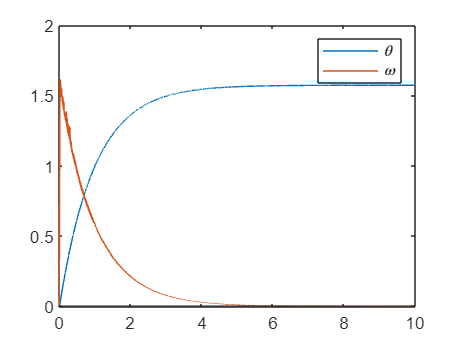



figure(); 
plot(t, x1, t, x2)
yline(delta_x1)
hold off; legend("\theta", "\omega")

## Control equivalente

La accion complementaria se define con el termino de perturbaicion / incertidumbre


$$\delta \;\left(x\right)=a\;\left\lbrack 1-\frac{g\left(x\right)}{\hat{g\;} \left(x\right)}\right\rbrack x_2 +h\left(x\right)\;\ldotp \frac{g\left(x\right)}{\hat{\;g} \left(x\right)}\hat{\;h} \left(x\right)$$


Definimos el modelo afín del sistema con 


$$g\left(x\right)=\frac{d_1 }{I}$$



$$h\left(x\right)=\frac{W_{\textrm{cp}} \;d_2 -W_m \;d_1 -W_b \;e}{I}\;\sin \left(x_1 \right)-\frac{\;\mu \;}{I}x_2$$
  

delta_x1 = 1.2 / 1.5

delta_x1 =    0.800000000000000


delta_x2 = a * (1 - 1.2 / 1.5) + 0.01

delta_x2 =    0.210000000000000



x1_max = 5; 
x2_max = 1; 

rho = delta_x1 * x1_max + delta_x2 * x2_max

rho =    4.210000000000000


## Almacenamiento de informacion

Guardamos unicamente las constantes beta y a para el diseño del SMC en la misma ruta que la carpeta de SMC. 

disp("Valores calculados")

Valores calculados


disp("  -a:" + num2str(a)); 

  -a:1


disp("  -beta:" + num2str(beta)); 

  -beta:100



% Guardar los datos 
%save("controllers/SMC/SMC.mat", "a", "beta");

Error using save
Cannot create 'SMC.mat' because 'controllers\SMC' does not exist.

## Grafica

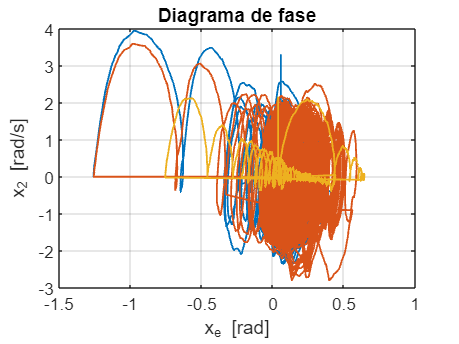

errorSMC = thetaSMC-ReferenceSMC;
errorSMCEq = thetaSMCEq-ReferenceSMCEq;
errorTanh = thetaTanh-ReferenceTanh;

figure()
plot(errorSMC*pi/180,omegaSMC, '-', 'LineWidth',1);
hold on; 
plot(errorSMCEq*pi/180,omegaSMCEq, '-', 'LineWidth',1);
plot(errorTanh*pi/180,omegaTanh, '-', 'LineWidth',1);
title("Diagrama de fase"); 
xlabel("x_e [rad]"); ylabel("x_2 [rad/s]");
grid on;

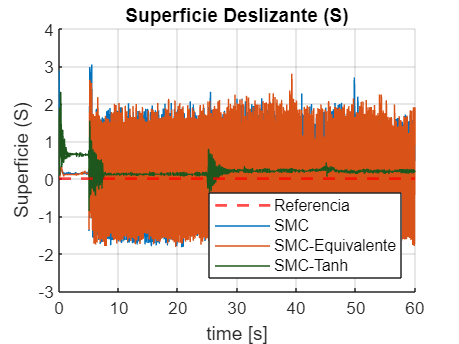


s1 = lowpass(a*errorSMC*pi/180+omegaSMC,30,1/2.5e-3);
s2 = lowpass(a*errorSMCEq*pi/180+omegaSMCEq,30,1/2.5e-3);
s3 = lowpass(a*errorTanh*pi/180+omegaTanh,30,1/2.5e-3);

figure()
yline(0, 'r--','LineWidth',1.5);
hold on; 
plot(timeSMC,s1)
plot(timeSMCEq,s2)
plot(timeTanh,s3,'Color',[30/255 87/255 29/255])
hold off
title("Superficie Deslizante (S)")
xlabel("time [s]"); 
ylabel("Superficie (S)");
xlim([0 60])
legend('Referencia','SMC','SMC-Equivalente', 'SMC-Tanh','Location','southeast')
grid on;

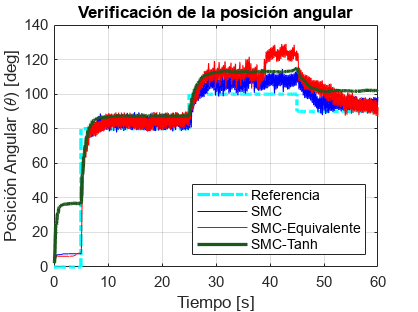


figure()
plot(timeSMC,ReferenceSMC,"c-.","LineWidth",2);
hold on
plot(timeSMC,thetaSMC,"b","LineWidth",0.5);
plot(timeSMCEq,thetaSMCEq,"r","LineWidth",0.5);
plot(timeTanh,thetaTanh,'Color',[30/255 87/255 29/255],"LineWidth",2);
hold off
grid on
xlim([0 60])
title('Verificación de la posición angular')
xlabel('Tiempo [s]')
ylabel('Posición Angular (\theta) [deg]')
legend('Referencia','SMC','SMC-Equivalente', 'SMC-Tanh','Location','southeast')